Here we test the developed numerical integration method using a second use case: the seismic resilience analysis in our paper submitted to RESS. The purpose of this test is to test the performance of the method under scenarios where we have inbalanced transition rates. Inbalanced transition rates always occur in reliability applications, as the repair rates are often much larger than failure rates (repair time is much smaller than failure times). The challenge of this fact is that to keep the assumption that only one transition happens in $\Delta$ valid, $\Delta$ must be very small (to the degree of repair times). On the other hand, this small $\Delta$ is a waste for failure times. The consequence might be a very slow computational performance.

## Use case description

We consider a Markov reward process with a state space $S={0,1,\cdots,4}$. The Q-matrix is

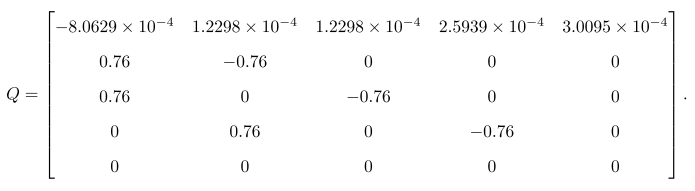

and reward vector is $\vec{r}=[0, 7.24, 18.2, 25.4, 25.4] \times 10^8$ (euros). The last state is an absorbing state. We consider an evaluation horizon of $40$ (years) and calculate $Pr(AR \ge 2.54\times10^9)$.

clear; clc;
%% Parameter definition
S = 1:5; % state space
pi = [1,0,0,0,0]; % initial distribution
% Define the Q-matrix
Q = [0, 1.2298e-4, 1.2298e-4, 2.5939e-4, 3.0095e-4;...
    .76, 0, 0, 0, 0;...
    .76, 0, 0, 0, 0;...
    0, .76, 0, 0, 0;...
    0, 0, 0, 0, 0];
for i = 1:5
    Q(i,i) = -1*sum(Q(i,:));
end
r = [0, 7.24, 18.2, 25.4, 25.4]*100/4; % Reward matrix
% Defining the structure para
para.S = S;
para.pi = pi;
para.Q = Q;
para.r = r;
addpath('..\');
x_max = 25.4*100/4; % Limit x values
T_max = 40; % Time limit

## Rectangle integration: Convergence rate

We first test directly the rectangle integration method and investigate its convergence rate. We consider different step sizes:


$$\frac{1}{4},\frac{1}{8},\frac{1}{16},\frac{1}{32},\cdots, \frac{1}{128}.$$


% Algorithm parameters
Delta = 1/4*(1/2).^(0:5);
result = zeros(1,length(Delta));
elasped_time = zeros(1,length(Delta));
for i = 1:length(Delta)
    fprintf('%d/%d\n',i,length(Delta));
    tic;
    result(i) = 1 - accumulated_reward_numit(T_max,x_max,Delta(i),para);
    elasped_time(i) = toc;
end

1/6
2/6
3/6
4/6
5/6
6/6


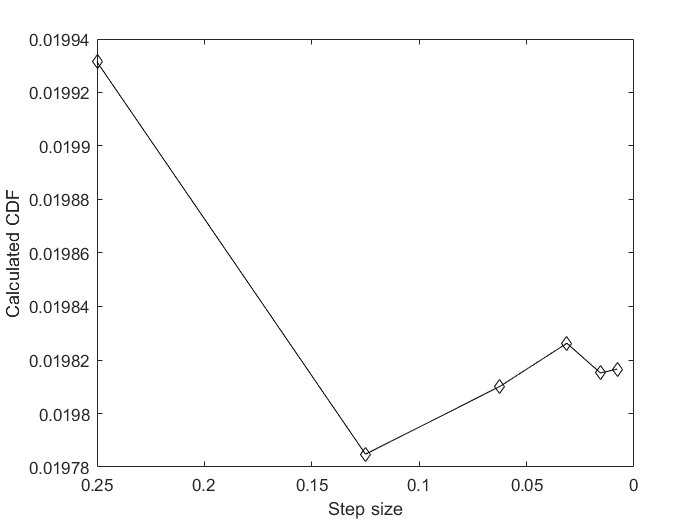

% save('result_use_case_2.mat');
% load('result_use_case_2.mat');
% Visualize result:
figure;
plot(Delta,result,'kd-');
set(gca,'Xdir','reverse');
xlabel('Step size');
ylabel('Calculated CDF');

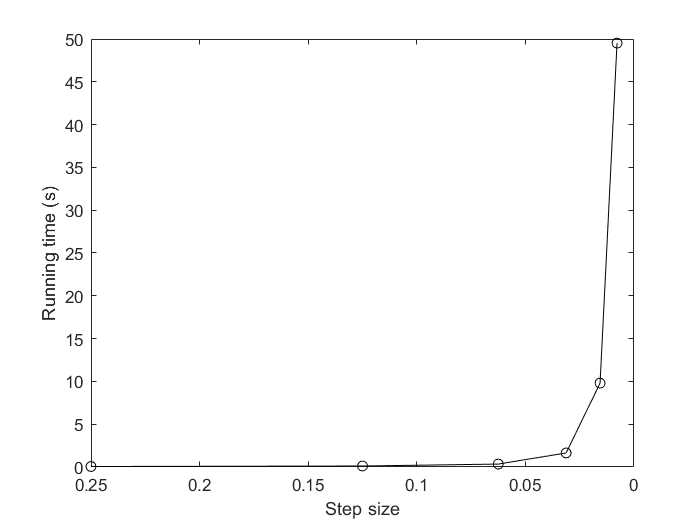

% Visualize running time
figure;
plot(Delta,elasped_time,'ok-')
set(gca,'Xdir','reverse');
xlabel('Step size');
ylabel('Running time (s)');

## Maximal step size considering the transition rates

For a Markov chain with transition rate matrix $Q$, the maximal step size $\Delta
$ should satify:

$\max_i P(n_{i,j}(\Delta)\ge 2) \le $A given threshold.

$\max_i \sum_{j=0}^1 e^{-\lambda_i \Delta} \frac{(\lambda_i \Delta)^j}{j!}$.

$\max_i \left(1-poisscdf(1,\lambda_i\Delta)\right) = \left(1-poisscdf(1,\min(\lambda_i)\Delta)\right) \le
$Threshold.

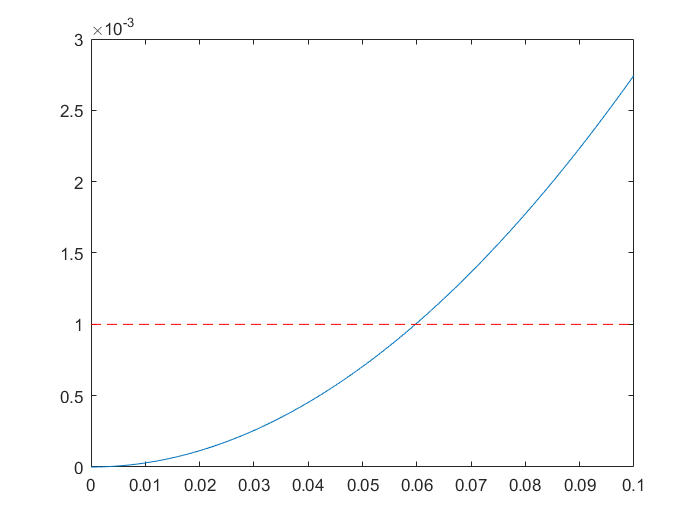

p_th = 1e-3; % Threshold probability.
% Take the exit rates.
exit_rate = zeros(1,size(Q,1));
for i = 1:size(Q,1)
    exit_rate(i) = -Q(i,i);
end
q_max = max(exit_rate); % Minimal exit rate.
% Define a handle to calculate the icdf of Poisson.
cal_exceed_prob = @(x) 1 - poisscdf(1, q_max*x);
x_trial = linspace(0,.1,1e3);
figure
plot(x_trial, cal_exceed_prob(x_trial),'-');
line([0,.1],[1e-3,1e-3],'Color','red','LineStyle','--');

## Test iteration until error tolerance

We designed a new function accumulated_reward_numit.m, which runs an iterative numerical integration with decreased sample size, until the difference between two adjacent simulations is below tol. We test its performance here.

% This is to test accumulated_reward_numit.m
clear; clc;
%% Parameter definition
S = 1:5; % state space
pi = [1,0,0,0,0]; % initial distribution
% Define the Q-matrix
Q = [0, 1.2298e-4, 1.2298e-4, 2.5939e-4, 3.0095e-4;...
    .76, 0, 0, 0, 0;...
    .76, 0, 0, 0, 0;...
    0, .76, 0, 0, 0;...
    0, 0, 0, 0, 0];
for i = 1:5
    Q(i,i) = -1*sum(Q(i,:));
end
r = [0, 7.24, 18.2, 25.4, 25.4]*100/4; % Reward matrix
% Defining the structure para
para.S = S;
para.pi = pi;
para.Q = Q;
para.r = r;
x_max = 25.4*100/4; % Limit x values
T_max = 40; % Time limit

%% Run the test.
Delta = 1/4*(1/2).^(1:7); % Search space.
tol = [1e-7];
format longE;
result_numit = zeros(size(tol));
elasped_time_numit = zeros(size(tol));
tic;
for i = 1:length(tol)
    fprintf('%d/%d\n',i,length(tol));
    result_numit(i) = 1 - accumulated_reward_numit(T_max,x_max,Delta,para,tol(i));
    elasped_time_numit(i) = toc;
    tic;
end

1/1


## Compare to Monte Carlo simulation.

We use a Monte Carlo simulation to compare the computational efficiencies and simulation accuracy. A sample size of $10^8

$ is used for Monte Carlo simulation. The errors of the Monte Carlo simulation is estimated by its $95\%$ confidence bound and the sample standard deviation. We have run the simulation and store the result in "result_benchmark.mat".

% Load the MC result.
load('result_benchmark_RESS_paper.mat');
% Calculate the cdf
result_MC = sum(P_O_time>x_max)/NS

result_MC =      1.981239000000000e-02


% Confidence interval
alpha = .05;
cal_sigma_hat = @(N,p) sqrt(1/(N-1).*(p.*(1-p)));
cal_ci = @(N,p,alpha) [p-norminv(1-alpha/2)*cal_sigma_hat(N,p),...
    p+norminv(1-alpha/2)*cal_sigma_hat(N,p)];
result_MC_CI = cal_ci(NS,result_MC,alpha)

result_MC_CI =      1.978507689139332e-02     1.983970310860668e-02


sample_std = cal_sigma_hat(NS,result_MC)

sample_std =      1.393551556157378e-05
